# 3D Animations in Matlab

From simple lines animations to more complex 3D models :)

## Animating Time-Histories: Impulse Response of a Dynamic System

dt = 0.05; % sample time [sec]
stop_time = 10; % [sec]
% Time vector
t = 0:dt:stop_time;
% Define the system as a low-pass and two-elastic modes
% -----------------------------------------------------
% Rigid dynamics, 2nd order low pass filter
wn_r = 2 * pi * 0.8;
chi_r = 1;
% 1st elastic mode properties
wn_e_1 = 2 * pi * 1.5;
chi_e_1 = 0.04;
% 2nd elastic mode properties
wn_e_2 = 2 * pi * 5;
chi_e_2 = 0.08;
% Construct the SISO transfer function
dyn_sys = tf(wn_r^2, [1, 2 * chi_r * wn_r, wn_r^2]);
dyn_sys = dyn_sys + tf([2 * chi_e_1 * wn_e_1, 0], [1, 2 * chi_e_1 * wn_e_1, wn_e_1^2]);
dyn_sys = dyn_sys + tf([2 * chi_e_2 * wn_e_1, 0], [1, 2 * chi_e_2 * wn_e_2, wn_e_2^2]);
% Compute the step response
y = step(dyn_sys, t);

### Animating the Plot the "Hard" Way

Now that we have the sine wave singal already defined, we can plot it  meanwhile refreshing the axis with the `hold on `and `hold off` functions.

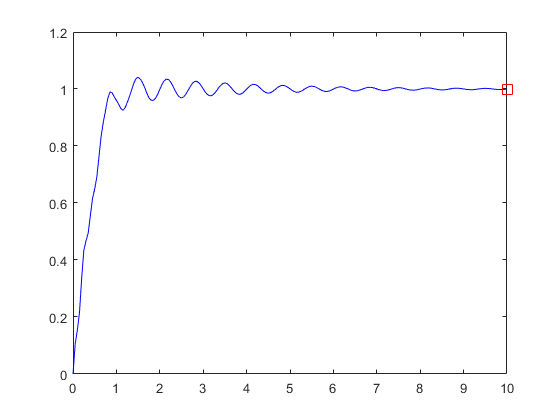

figure;
hsp = subplot(1, 1, 1);
grid(hsp, 'on');
box(hsp, 'on');
tic;
for i = 1:length(t)
    hold(hsp, 'off');
    plot(t(1:i), y(1:i), '-b');
    hold(hsp, 'on');
    plot(t(i), y(i), 'sr', 'MarkerSize', 10);
    xlim(hsp, [0, stop_time]);
    ylim(hsp, [0, +1.2]);
    drawnow;
end

fprintf('Elapsed time = %4.1f\n', toc);

Elapsed time =  4.6


### Animating the Plot the "Easy" Way

There's an easier way to to this using the `'XDataSource' `and `'YDataSource' `(and` 'ZDataSource'`) lines' properties and `refershdata` function, getting rid of the `hold on `and `hold off` functions.

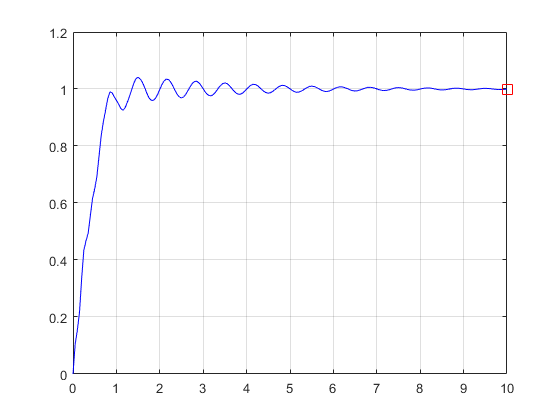

figure;
hsp = subplot(1, 1, 1);
hold(hsp, 'on');
h_evol      = plot(t(1), y(1), '-b', 'XDataSource', 'time', 'YDataSource', 'y_evolution');
h_marker    = plot(t(1), y(1), 'sr', 'XDataSource', 't_current', 'YDataSource', 'y_current', 'MarkerSize', 10);
xlim(hsp, [0, stop_time]);
ylim(hsp, [0, +1.2]);
grid(hsp, 'on'); 
box(hsp,  'on');
tic;
for i = 1:length(t)
    time = t(1:i);
    y_evolution = y(1:i);
    t_current = t(i);
    y_current = y(i);
    refreshdata(h_evol, 'caller');
    refreshdata(h_marker, 'caller')
    drawnow;
    if dt * i - toc > 0
        pause(max(0, dt * i - toc))
    end
end

fprintf('Elapsed time = %4.1f\n', toc);

Elapsed time = 10.1


## Plotting Complex 3D Objects

The easiest way to plot 3D objects is to import them from an Steareolitographic format file, which includes information about the vertex and faces of the objects.

### stlTools

You can easily import any stl file using this free-toolbox ([stlTools](https://es.mathworks.com/matlabcentral/fileexchange/51200-stltools))

% Add path to stlTools
% You can download the package for free from: 
% https://es.mathworks.com/matlabcentral/fileexchange/51200-stltools
addpath('./stlTools/');

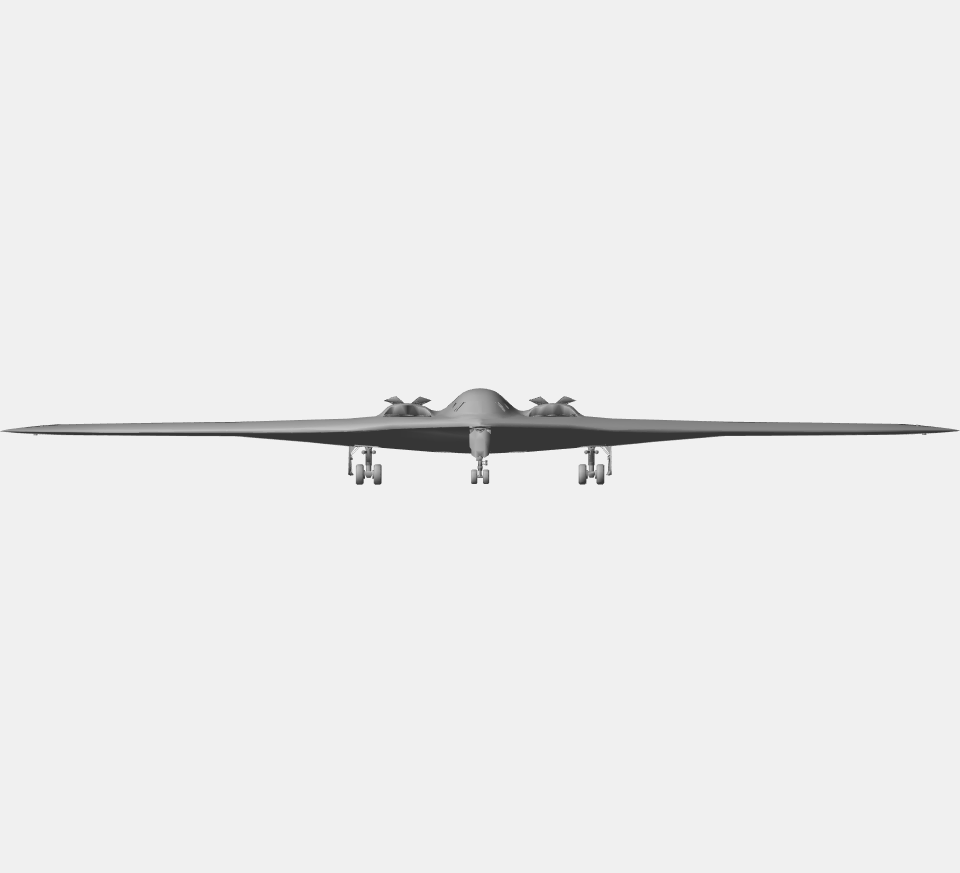

% Add path to stl 3D models
addpath(genpath('./3D_models/'));

% Read the STL file
[model.vertices, model.faces, ~, ~] = stlRead('B-2_Spirit.stl');

% Define the figure properties
figure;
AX = axes('position', [0, 0, 1, 1]);
axis off
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', [scrsz(3)/40, scrsz(4)/12, scrsz(3)/2, scrsz(3)/2.2], 'Visible', 'on');
set(AX, 'color', 'none');
axis('equal')
hold on;
cameratoolbar('Show')
axis off;
% Plot the 3D figure
hp = patch(model,  'FaceColor',  0.7 * [1, 1, 1], ...
    'EdgeColor',        'none',        ...
    'FaceLighting',     'gouraud',     ...
    'AmbientStrength',   0.15);
% Set the camlight and the material
camlight('left');
material('dull');

## Graphical Objects Transformations and Grouping Properties

Matlab has two great functions to make our life easier when manipulating 3D objects:

- `hgtransform`

- `makehgtform`

We will use these built-in functions to apply translation and rotation transformations to the different parts of our 3D model in a straightforward way, with just two lines of code.

In Matlab, graphical objects like lines, surfaces, and patches can be grouped to share a common parent defining a set of spatial transformations (translation, scaling, and rotation) that apply to every child.

The transformation group handle is created using the `hgtransform` function, and the group association is performed via the `‘Parent’` property of the graphical objects. Here there is a simple example from MATLAB's documentation:

close all;
ax = axes('XLim', [-1.5 1.5], 'YLim', [-1.5 1.5], 'ZLim', [-1.5 1.5]);
axis(ax, 'equal')
view(3)
grid on; box on;
t = hgtransform('Parent', ax);
[x,y,z] = cylinder([.2 0]);
h(1) = surface( x,  y,  z, 'FaceColor', 'white');
h(2) = surface( x,  y, -z, 'FaceColor', 'white');
h(3) = surface( z,  x,  y, 'FaceColor', 'green');
h(4) = surface(-z,  x,  y, 'FaceColor', 'red');
h(5) = surface( y,  z,  x, 'FaceColor', 'white');
h(6) = surface( y, -z,  x, 'FaceColor', 'white');
set(h, 'Parent', t)
tic;
for r = 1:.1:2*pi
    % Z-axis rotation matrix
    Rz = makehgtform('zrotate', r);
    % Scaling matrix
    Sxy = makehgtform('scale', r/4);
    % Concatenate the transforms and
    % set the transform Matrix property
    set(t, 'Matrix',Rz*Sxy)
    drawnow limitrate;
    % Control the animation speed
    if dt * 10 * r - toc > 0
        pause(max(0, 10 * dt * r - toc))
    end
end

What’s the advantage of all of this? 

How can we animate the following object?

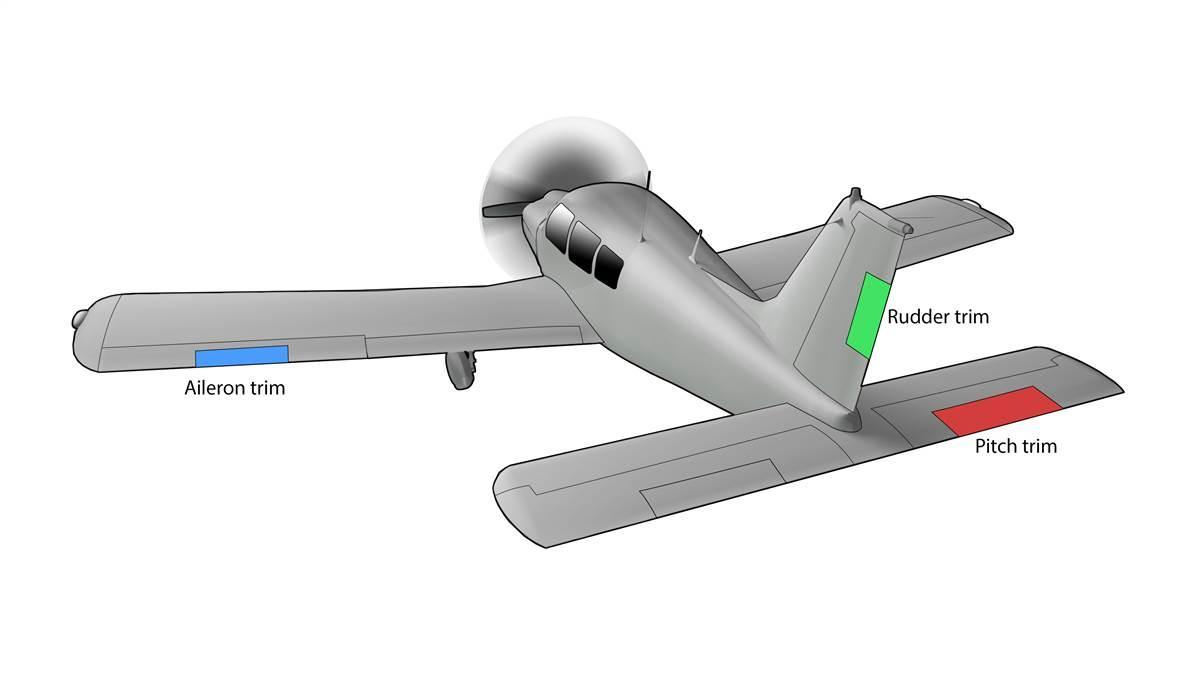

The grouping or ‘parent’ strategy we would follow to solve this problem is depicted in the figure below.

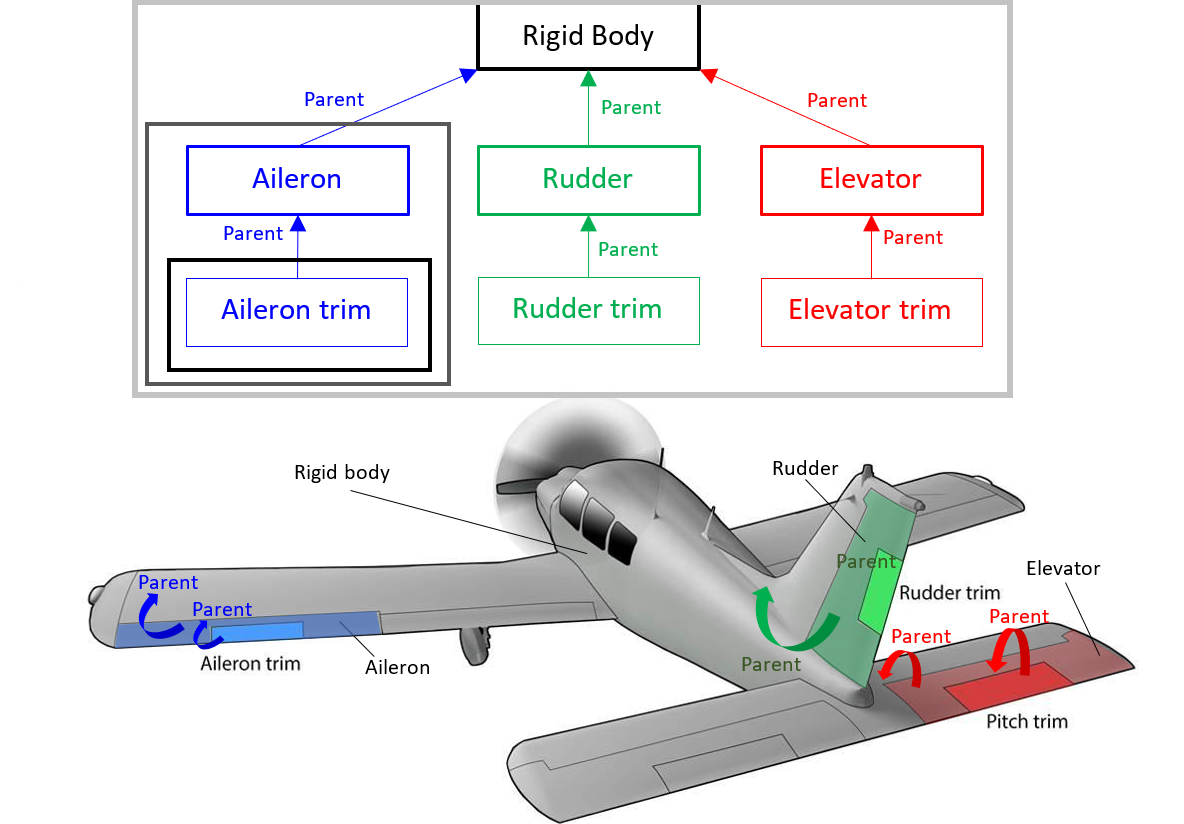

Do you see the advantage now?

## Animating a Single Moveable Flight Control Surface

In this example we will load the mesh of a Saab Gripen fighter jet. We will focus on how to move the port canard / foreplane.

I have already splitted the model into these parts:

- *AB_Left.stl       *

- *AB_Right.stl      *

- *Body.stl*

- *Canopy_Front.stl  *

- *Canopy_Rear.stl   *

- **Elevon_Left.stl   **

- **Elevon_Right.stl  **

- **FP_Left.stl       **

- **FP_Right.stl      **

- **LE_Left.stl       **

- **LE_Right.stl      **

- **Rudder.stl  **

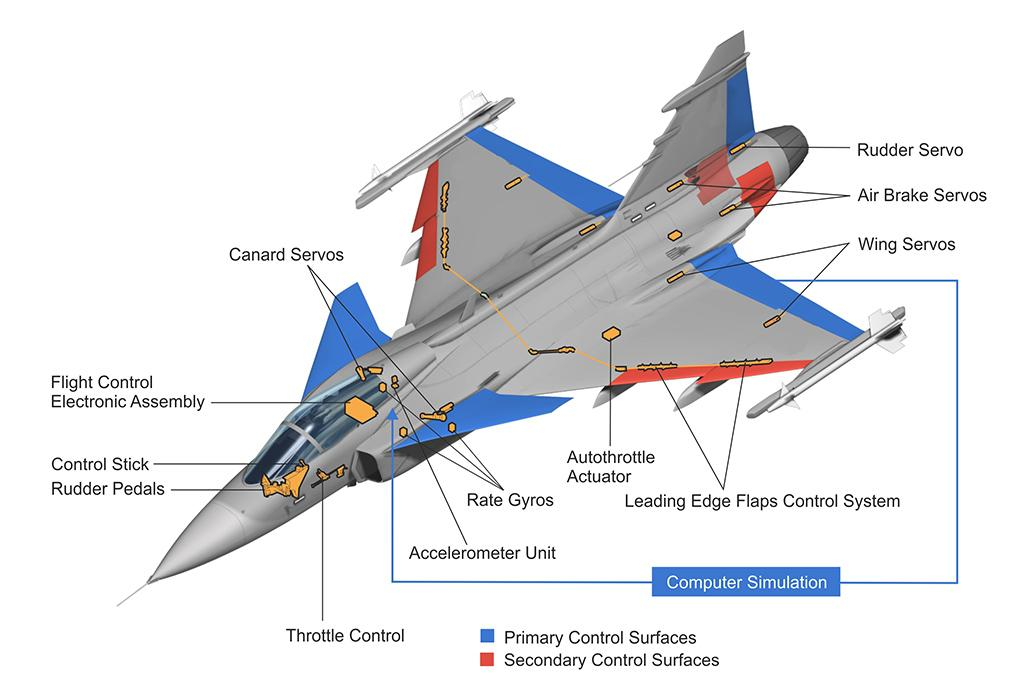

First we need to define the rotation axis of the fight control surface we want to animate. So first we plot the patch representing the rigid parts and the flight control surface, to then pick the rotation point and rotation vector using the "pick" tool.

### Loading the Rigid-Body Parts

clearvars;
close all;
% Define the list of parts which will be part of the rigid aircraft body
rigid_body_list   = {     'Body.stl',   'AB_Left.stl',  'AB_Right.stl', 'Canopy_Front.stl', 'Canopy_Rear.stl'};
% Define the color of each part
rigid_body_colors = {0.8 * [1, 1, 1], 0.6 * [1, 1, 1], 0.6 * [1, 1, 1],    0.1 * [1, 1, 1],   0.1 * [1, 1, 1]};
% Define the transparency of each part
alphas            = [              1,               1,               1,                0.9,               0.9] * 0.4;
% Define the model offset vector to center the A/C body at the Center of Gravity
% (CG)
offset_3d_model   = [8678.85, -15.48, 606.68];
% Rigid body parts
for i = 1:length(rigid_body_list)
    Model3D.Aircraft(i).model = rigid_body_list{i};
    Model3D.Aircraft(i).color = rigid_body_colors{i};
    Model3D.Aircraft(i).alpha = alphas(i);
    % Read the *.stl file
   [Model3D.Aircraft(i).stl_data.vertices, Model3D.Aircraft(i).stl_data.faces, ~, Model3D.Aircraft(i).label] = stlRead(rigid_body_list{i});
    Model3D.Aircraft(i).stl_data.vertices  = Model3D.Aircraft(i).stl_data.vertices - offset_3d_model;
end

### Loading the Moveable Flight Control Surface

control_surface = 'FP_left.stl';
% Load the flight control surface
[Model3D.Control.stl_data.vertices, Model3D.Control.stl_data.faces, ~, ~] = stlRead(control_surface);
Model3D.Control.stl_data.vertices  = Model3D.Control.stl_data.vertices - offset_3d_model;

### Plot the 3D Parts and Pick the Rotation Point and Rotation Vector

% Get maximum dimension to plot the circles afterwards
AC_DIMENSION = max(max(sqrt(sum(Model3D.Aircraft(1).stl_data.vertices.^2,2))));
for i=1:length(Model3D.Control)
    AC_DIMENSION = max(AC_DIMENSION,max(max(sqrt(sum(Model3D.Control(i).stl_data.vertices.^2,2)))));
end
% Define the figure properties
AX = axes('position',[0.0 0.0 1 1]);
axis off
scrsz = get(0,'ScreenSize');
set(gcf,'Position',[scrsz(3)/40 scrsz(4)/12 scrsz(3)/2*1.0 scrsz(3)/2.2*1.0],'Visible','on');
set(AX,'color','none');
axis('equal')
hold on;
cameratoolbar('Show')
% Plot objects
% -------------------------------------------------------------------------
% Plot airframe
for i = 1:length(Model3D.Aircraft)
    AV = patch(Model3D.Aircraft(i).stl_data,  'FaceColor',        Model3D.Aircraft(i).color, ...
        'EdgeColor',        'none',        ...
        'FaceLighting',     'gouraud',     ...
        'FaceAlpha',        Model3D.Aircraft(i).alpha, ...
        'AmbientStrength',   0.15);
end
CONT(length(Model3D.Control))=0;
% Plot controls
for i=1:length(Model3D.Control)
    CONT(i) = patch(Model3D.Control(i).stl_data,  'FaceColor',        [1, 0, 0], ...
        'EdgeColor',        'none',        ...
        'FaceLighting',     'gouraud',     ...
        'AmbientStrength',  0.15);
end
% Fixing the axes scaling and setting a nice view angle
axis('equal');
axis([-1 1 -1 1 -1 1] * 1.0 * AC_DIMENSION)
set(gcf,'Color',[1 1 1])
axis off
view([30 10])
% Add a camera light, and tone down the specular highlighting
camlight('left');
material('dull');

Once we have the rotation point and the rotation axis, we will check we have not made any mistake.Let's see the results

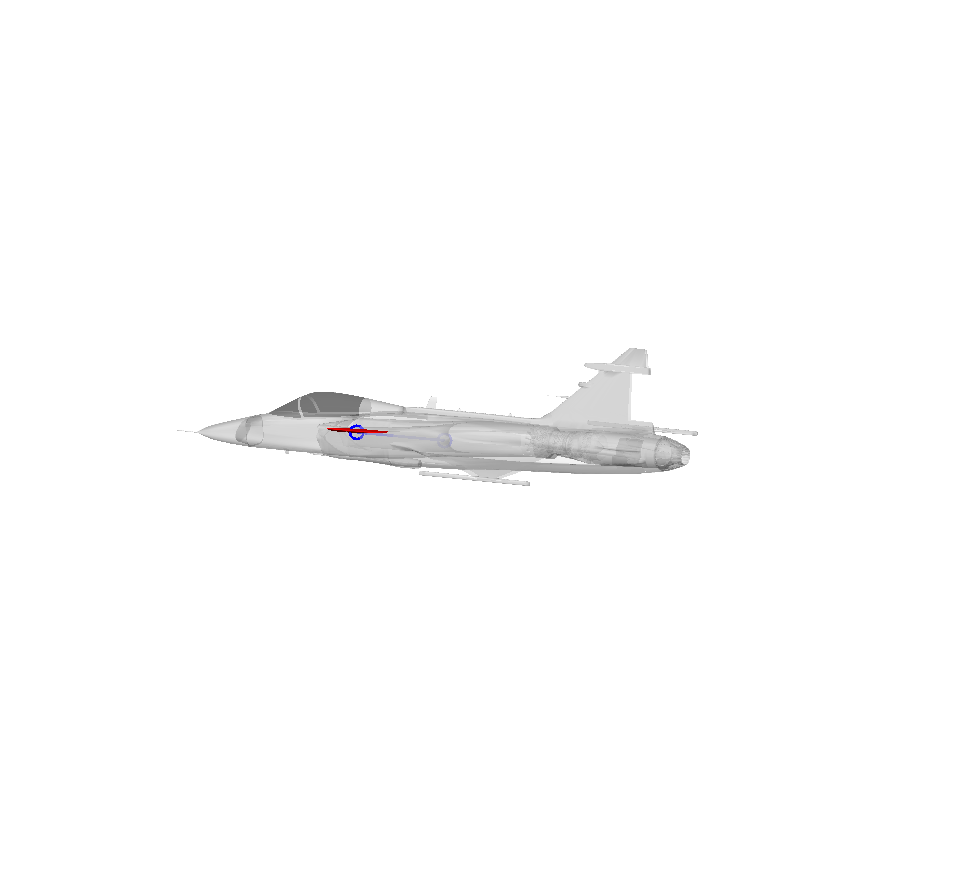

% Define the flight control surface rotation point
Model3D.Control.rot_point = [5719,  -996.6,  600.0]-offset_3d_model;

% Define the rotation vector
Model3D.Control.rot_vect =  [0,  1, -0.2];

% Check the points picked
p = Model3D.Control.rot_point;
vect = Model3D.Control.rot_vect;
plot3(p(1)+[0, AC_DIMENSION*vect(1)/2], p(2)+[0, AC_DIMENSION*vect(2)/2], p(3)+[0, AC_DIMENSION*vect(3)/2], 'b-o', 'MarkerSize', 10, 'LineWidth', 2);

 Now we are ready to define the transformation groups and make a test animation:

1. Initialize the figure and set the camera properties

close all;
% Define the figure properties
AX = axes('position',[0.0 0.0 1 1]);
axis off
scrsz = get(0,'ScreenSize');
set(gcf,'Position', [scrsz(3)/40 scrsz(4)/12 scrsz(3)/2*1.0 scrsz(3)/2.2*1.0],'Visible','on');
set(AX,'color','none');
axis('equal')
hold on;
cameratoolbar('Show')

2. Define the transformation groups dependencies

% Initializate transformation group handles
% -------------------------------------------------------------------------
% Aircraft transformation group handle
AV_hg         = hgtransform('Parent', AX, 'tag', 'ACRigidBody');
% controls_deflection_deg transformation group handles
CONT_hg       = zeros(1, length(Model3D.Control));
for i = 1:length(Model3D.Control)
    CONT_hg(i) = hgtransform('Parent', AV_hg, 'tag', sprintf('Control%d', i));
end

3. Define the aircraft and the flight control surface movement

% Define the time history of the flight control surface deflection
dt = 0.05;
stop_time = 20;
t = 0:dt:stop_time;
% Chirp signal
surface_angle = 50 * pi / 180 * sin(2 * pi * 0.5*(1 + 1.6*t)); % [rad]
% Aircraft is rolling to the right
roll_angle = 5 * t * pi / 180; % [rad]

4. Plot the 3D elements and assign them to the transformation groups

% Plot objects
% -------------------------------------------------------------------------
% Plot airframe
for i = 1:length(Model3D.Aircraft)
    AV = patch(Model3D.Aircraft(i).stl_data, 'FaceColor', Model3D.Aircraft(i).color, ...
        'EdgeColor',        'none',        ...
        'FaceLighting',     'gouraud',     ...
        'AmbientStrength',   0.15, ...
        'Parent',            AV_hg);
end
CONT(length(Model3D.Control))=0;
% Plot controls
for i=1:length(Model3D.Control)
    CONT(i) = patch(Model3D.Control(i).stl_data, 'FaceColor', [1, 0, 0], ...
        'EdgeColor',        'none',        ...
        'FaceLighting',     'gouraud',     ...
        'AmbientStrength',   0.15, ...
        'Parent',            CONT_hg(i));
end
% Fixing the axes scaling and setting a nice view angle
axis('equal');
axis([-1 1 -1 1 -1 1] * 1.0 * AC_DIMENSION)
set(gcf,'Color',[1 1 1])
axis off
view([30 10])
% Add a camera light, and tone down the specular highlighting
camlight('left');
material('dull');

5. Animate the objects 

tic;
for i = 1:length(t)
    
    % Rotate the aircraft rigid-body
    M = makehgtform('xrotate', -roll_angle(i));
    set(AV_hg, 'Matrix', M);
    
    % controls_deflection
    for j=1:length(Model3D.Control)
        M1 = makehgtform('translate', -Model3D.Control(j).rot_point);   % Put the surface rotation point at 0,0,0
        M2 = makehgtform('axisrotate', Model3D.Control(j).rot_vect, surface_angle(i));  % Rotate the surface
        M3 = makehgtform('translate', Model3D.Control(j).rot_point);  % Restore the position
        set(CONT_hg(j), 'Matrix', M3 * M2 * M1);
    end
    
    % Control the animation speed
    if dt * i - toc > 0
        pause(max(0, dt * i - toc))
    end
end

Error using matlab.graphics.primitive.Transform/set
Invalid or deleted object.

## Preparing a Single-Agent 3D Model

Now that we have learnt how to move one control surface, let's go fo the rest of them and prepare the 3D model to be contained in a single data structure.

clearvars;
% Add path to stlTools
% You can download the package for free from: 
% https://es.mathworks.com/matlabcentral/fileexchange/51200-stltools
addpath('./stlTools');


% Set the name of the mat file containing all the info of the 3D model
MatFileName = './3D_models/SAAB_GRIPEN_MULTI_BODY.mat';

% Define the list of parts which will be part of the rigid aircraft body
rigid_body_list   = {     'Body.stl',   'AB_Left.stl',  'AB_Right.stl', 'Canopy_Front.stl', 'Canopy_Rear.stl'};

% Define the color of each part
rigid_body_colors = {0.8 * [1, 1, 1], 0.6 * [1, 1, 1], 0.6 * [1, 1, 1],    0.1 * [1, 1, 1],   0.1 * [1, 1, 1]};

% Define the transparency of each part
alphas            = [              1,               1,               1,                0.9,               0.9];

% Define the model ofset to center the A/C Center of Gravity
offset_3d_model   = [8678.85, -15.48, 606.68];

% Define the controls 
ControlsFieldNames = {...
'model'              'label',             'color',                             'rot_point',            'rot_vect', 'max_deflection'};
Controls = {                                                                                                       
'FP_Right.stl',       'FP_R',   0.3*[0.8, 0.8, 1], [5719,   996.6,  600.0]-offset_3d_model,            [0,  1,  0.2], [-30, +30];
'FP_Left.stl',        'FP_L',   0.3*[0.8, 0.8, 1], [5719,  -996.6,  600.0]-offset_3d_model,            [0,  1, -0.2], [-30, +30];
'LE_Left.stl',        'LE_L',   0.3*[0.8, 0.8, 1], [9267, -2493.0,  380.2]-offset_3d_model, [ 0.7849, -0.6197,    0], [ -1, +30];
'LE_right.stl',       'LE_R',   0.3*[0.8, 0.8, 1], [9267, +2493.0,  380.2]-offset_3d_model, [-0.7849, -0.7197,    0], [ -1, +30];
'Rudder.stl',          'RUD',   0.3*[0.8, 0.8, 1], [12930,    0.0, 1387.0]-offset_3d_model,            [0, 0,    -1], [-30, +30];
'Elevon_Left.stl',  'FLAP_L',   0.3*[0.8, 0.8, 1], [11260, -860.9,  368.3]-offset_3d_model, [+0.0034,  0.9999,    0], [-30, +30];
'Elevon_Right.stl', 'FLAP_R',   0.3*[0.8, 0.8, 1], [11260, +860.9,  368.3]-offset_3d_model, [-0.0034,  0.9999,    0], [-30, +30];
};

%% Definition of the Model3D data structure
% Rigid body parts
for i = 1:length(rigid_body_list)
    Model3D.Aircraft(i).model = rigid_body_list{i};
    Model3D.Aircraft(i).color = rigid_body_colors{i};
    Model3D.Aircraft(i).alpha = alphas(i);
    % Read the *.stl file
   [Model3D.Aircraft(i).stl_data.vertices, Model3D.Aircraft(i).stl_data.faces, ~, Model3D.Aircraft(i).label] = stlRead(rigid_body_list{i});
    Model3D.Aircraft(i).stl_data.vertices  = Model3D.Aircraft(i).stl_data.vertices - offset_3d_model;
end

% Controls parts
for i = 1:size(Controls, 1)
    for j = 1:size(Controls, 2)
        Model3D.Control(i).(ControlsFieldNames{j}) = Controls{i, j};
    end
    % Read the *.stl file
    [Model3D.Control(i).stl_data.vertices, Model3D.Control(i).stl_data.faces, ~, ~] = stlRead( Model3D.Control(i).model);
    Model3D.Control(i).stl_data.vertices = Model3D.Control(i).stl_data.vertices - offset_3d_model;
end

%% Save mat file
save(MatFileName, 'Model3D');

Now check that we have made no errors

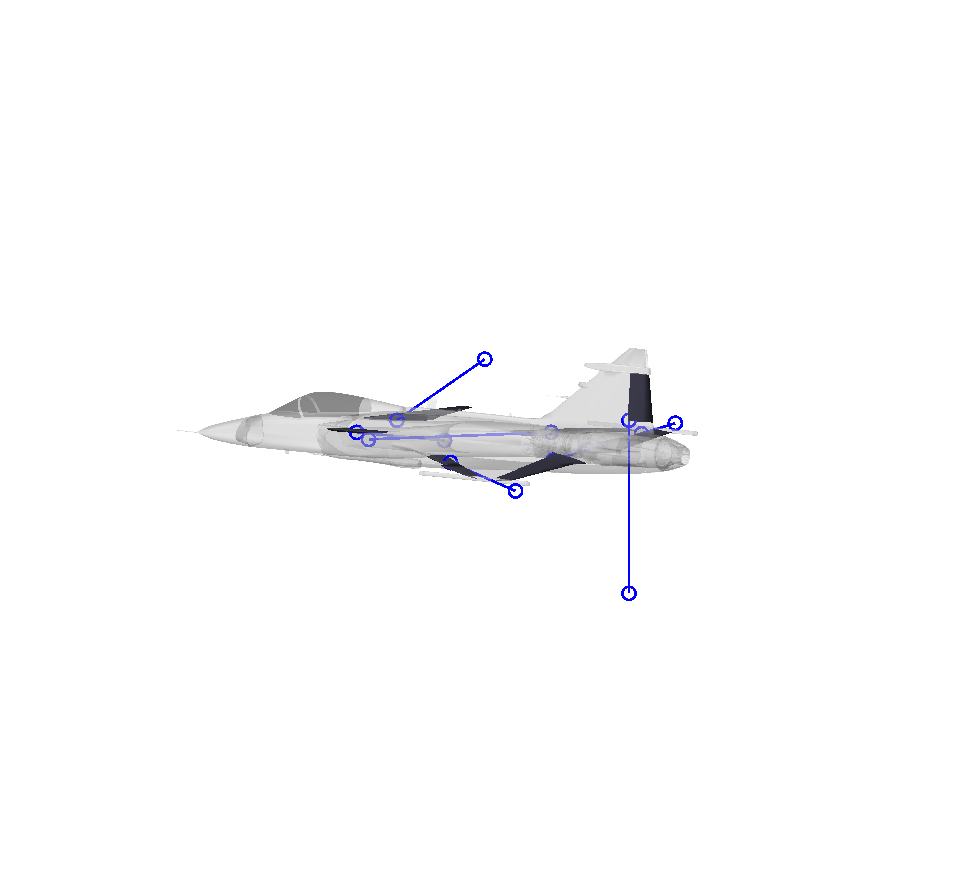

clearvars;
close all;
% Set the name of the mat file containing all the info of the 3D model
MatFileName = './3D_models/SAAB_GRIPEN_MULTI_BODY.mat';
load(MatFileName);%% Check the results
% Get maximum dimension to plot the circles afterwards
AC_DIMENSION = max(max(sqrt(sum(Model3D.Aircraft(1).stl_data.vertices.^2, 2))));
for i=1:length(Model3D.Control)
    AC_DIMENSION = max(AC_DIMENSION, max(max(sqrt(sum(Model3D.Control(i).stl_data.vertices.^2, 2)))));
end
% Define the figure properties
AX = axes('position',[0.0 0.0 1 1]);
axis off
scrsz = get(0,'ScreenSize');
set(gcf,'Position',[scrsz(3)/40 scrsz(4)/12 scrsz(3)/2*1.0 scrsz(3)/2.2*1.0], 'Visible', 'on');
set(AX,'color','none');
axis('equal')
hold on;
cameratoolbar('Show')
% Plot objects
% -------------------------------------------------------------------------
% Plot airframe
for i = 1:length(Model3D.Aircraft)
    AV = patch(Model3D.Aircraft(i).stl_data, 'FaceColor', Model3D.Aircraft(i).color, ...
        'EdgeColor',        'none',        ...
        'FaceLighting',     'gouraud',     ...
        'FaceAlpha',         0.3, ...
        'AmbientStrength',   0.15);
end
CONT(length(Model3D.Control))=0;
% Plot controls
for i=1:length(Model3D.Control)
    CONT(i) = patch(Model3D.Control(i).stl_data, 'FaceColor', Model3D.Control(i).color, ...
        'EdgeColor',        'none',        ...
        'FaceLighting',     'gouraud',     ...
        'AmbientStrength',   0.15);
    % Plot the rotation point and the rotation axis of each control
    % (double-check correct implementation and rotation direction of each
    % control surface)
    p = Model3D.Control(i).rot_point;
    vect = Model3D.Control(i).rot_vect;
    plot3(p(1)+[0, AC_DIMENSION*vect(1)/2], p(2)+[0, AC_DIMENSION*vect(2)/2], p(3)+[0, AC_DIMENSION*vect(3)/2], 'b-o', 'MarkerSize', 10, 'LineWidth', 2);
end
% Fixing the axes scaling and setting a nice view angle
axis('equal');
axis([-1 1 -1 1 -1 1] * 2.0 * AC_DIMENSION)
set(gcf,'Color',[1 1 1])
axis off
view([30 10])
zoom(2.0);
% Add a camera light, and tone down the specular highlighting
camlight('left');
material('dull');